# NULLCLINEs STRUCTURE

In this example, we will use an implementation of Fitz-Hugh Nagumo model and we will illustrate how to import, use and visualize the nullclines structure. Specifically, the Fitz-Hugh Nagumo model presents the following ODEs,

$\begin{array}{l}
\dot{x} =\tau \;\left(x-x^3 -y+I\right)\\
\dot{y} =x+A-\textrm{By}
\end{array}$ (1)

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% XPPLORE
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

The first operation consists in reading the model implemented in the `.ode` file.

% MODEL
M = Func_ReadModel('fhn.ode');

## SIMULATION

The simulation can be loaded in MATLAB through the function *Func_ReadData. *This function takes as input the model `M` and the name of the `.dat` file. The output will be a structure containing several fields equal to the number of variables in the `.ode` file (both dynamical and auxiliary variables) increased by 1. Hence, the fields of the structure are the temporal variable `t` and the variables implemented in the `.ode` model.

% DATA
D = Func_ReadData(M,'sim.dat');

## NULLCLINEs

For what it concerns the nullclines, the structure is a bit more complicated. First of all, the user is required to export a file whose name has the following configuration *TEXT_x_y.dat.* Where,

- *TEXT*: It is a generic sequence of alpha-numerical characters with no underscore ("_") in it.

- *x/y*: It is the name of the x/y-axis variable. The name must corresponds to the name of the dynamical variable implemented in the `.ode` file.

In this example the name of the file is *nc_y_x.dat. *y is the variable along the x-axis while x is the variable along the y-axis. You can load the data through the function *Func_ReadNullclines. *This function returns a structure with two fields, NCx and NCy (where *x* and *y* are the name of the x/y-axis variables you have specified). These are two structures containing the pair of points exported in the `.dat` file.

% NULLCLINEs
NC = Func_ReadNullclines('nc_y_x.dat');

## VISUALIZATION

Finally, to visualize the nullclines, the user can use the function *Func_VisualizeNullclines*. This requires as input, the nullcline structure to be visualized (mandatory input), and an optional costumized option structure in case the user wants to change the colours of the nullclines. If so, the default option structure can be created by using the function *Func_DOBD. *This can be changed by interveening on the field `opts.NC.C`. This is a cell array with two entries representing the colours used to visualize the nullclines. Specifically, the first/second will be applied to the x/y-axis variable nullcline. In this case, we visualize a simulation of the model as well. This can be done by using the *plot* function.

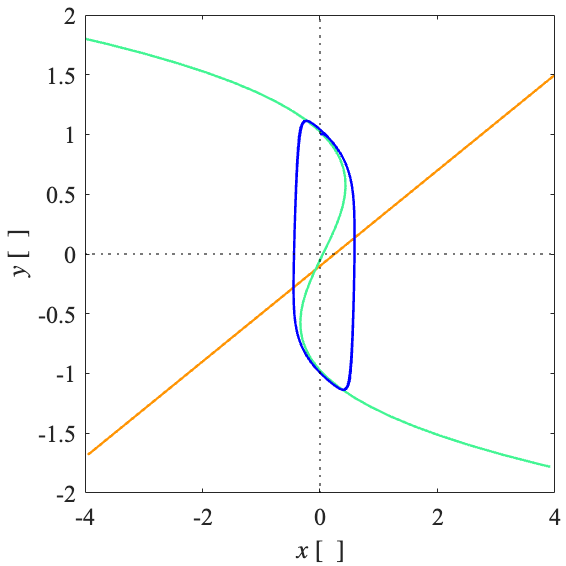

% VISUALIZATION
fig = figure();

Func_VisualizeNullclines(NC);

hold on
plot(D.y,D.x,'Color','b','LineWidth',1.2)
hold off

xline(0,'Color','k','LineStyle',':','LineWidth',0.8)
yline(0,'Color','k','LineStyle',':','LineWidth',0.8)

xlabel('$x$ [\ ]','interpreter','latex')
ylabel('$y$ [\ ]','interpreter','latex')

Func_FigStyle(fig)